clc, clear all, close all;

path = pwd + "/15bpm5c40sps_1-50sw/";
fullpath = join([path, "16_rawvals.csv"], "");
num = readmatrix(fullpath);

ids = ["e280116060000205403de047", "e280116060000205403e136b"];
epc = readtable(fullpath).epc96(:);

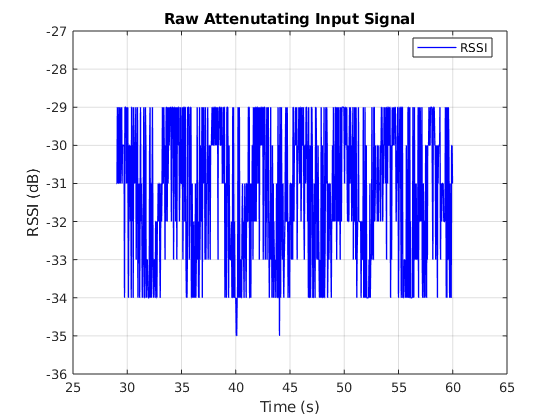


time_main = num(:, 3);
time_main = time_main(epc == ids(1));
rssi_main = num(:, 2);
rssi_main = rssi_main(epc == ids(1));

time_ref = num(:, 3);
time_ref = time_ref(epc == ids(2));
rssi_ref = num(:, 2);
rssi_ref = rssi_ref(epc == ids(2));

figure;
plot(time_main, rssi_main, 'b', 'linewidth', 1);
xlabel('Time (s)'), ylabel('RSSI (dB)');
grid on, title('Raw Attenutating Input Signal');
legend('RSSI', "Location", "best");
xlim([25 65]);
ylim([-36 -27]);

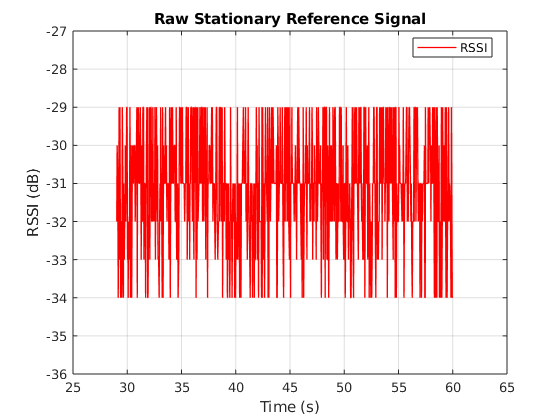


figure;
plot(time_ref, rssi_ref, 'r', 'linewidth', 1);
xlabel('Time (s)'), ylabel('RSSI (dB)');
grid on, title('Raw Stationary Reference Signal');
legend('RSSI', "Location", "best");
xlim([25 65]);
ylim([-36 -27]);

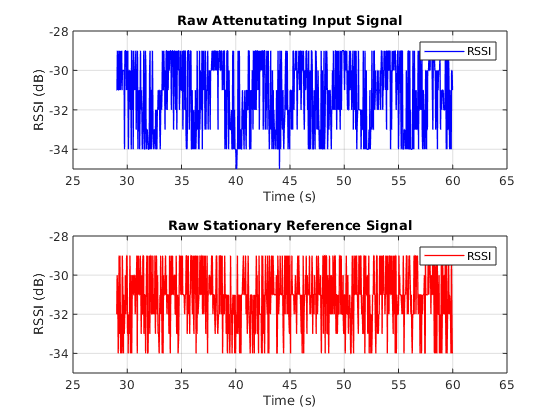


figure;
tiledlayout(2, 1);

ax1 = nexttile;
plot(time_main, rssi_main, 'b', 'linewidth', 1);
xlabel('Time (s)'), ylabel('RSSI (dB)');
grid on, title('Raw Attenutating Input Signal');
legend('RSSI', "Location","best");
xlim([25, 65]);
ylim([-35 -28]);

ax2 = nexttile;
plot(ax2, time_ref, rssi_ref, 'r', 'linewidth', 1);
xlabel('Time (s)'), ylabel('RSSI (dB)');
grid on, title('Raw Stationary Reference Signal');
legend('RSSI', "Location", "best");
xlim([25, 65]);
ylim([-35 -28]);